# Modelling Jakobshavn Isbrae Glacier

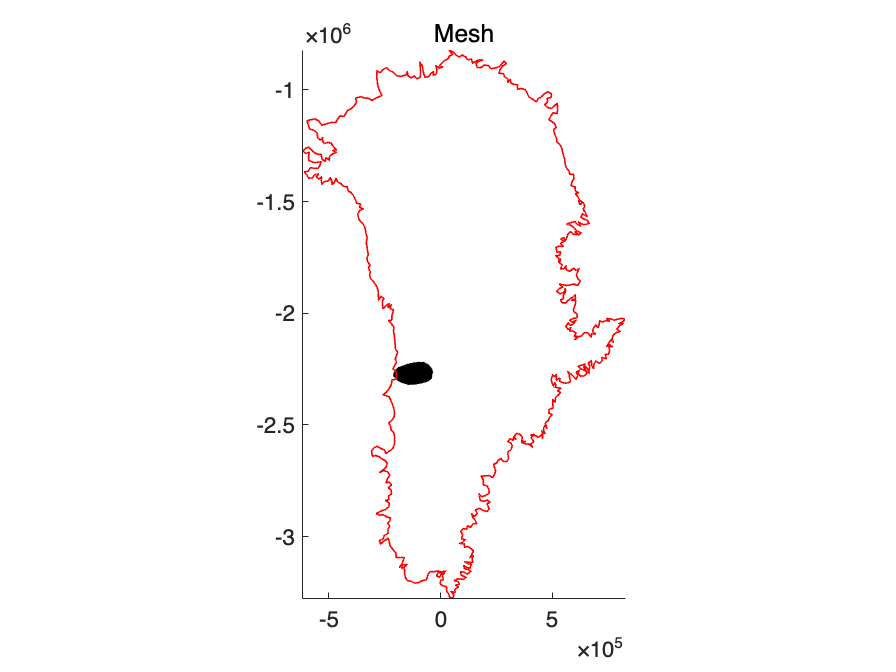

% First capture the geometry from shapefile - convert .shp (GIS) to .exp
cd '/Users/rishi/Desktop/ISSM/examples/Jakobshavn'
shp2exp('Jakobshavn.shp','Jakobshavn.exp');

% Use the .exp file to make the triangular mesh
md = triangle(model,'/Users/rishi/Desktop/ISSM/examples/Jakobshavn/Jakobshavn.exp',2000);

% plot the mesh with the greenland bondary to observed its location
plotmodel(md,'data','mesh')
hold on
expdisp('/Users/rishi/Desktop/ISSM/examples/Helheim/GreenlandOutline.exp')

## Interpolate observed surface velocities onto the current mesh

[velx, vely]=interpJoughinCompositeGreenland(md.mesh.x,md.mesh.y,...
    '/Users/rishi/Desktop/ISSM/examples/Data/');
vel = sqrt(velx.^2+vely.^2);

% Refine mesh based on surface velocitie s
md=bamg(md,'hmin',200,'hmax',1500,'field',vel,'err',5);

Anisotropic mesh adaptation
   new number of triangles = 18303


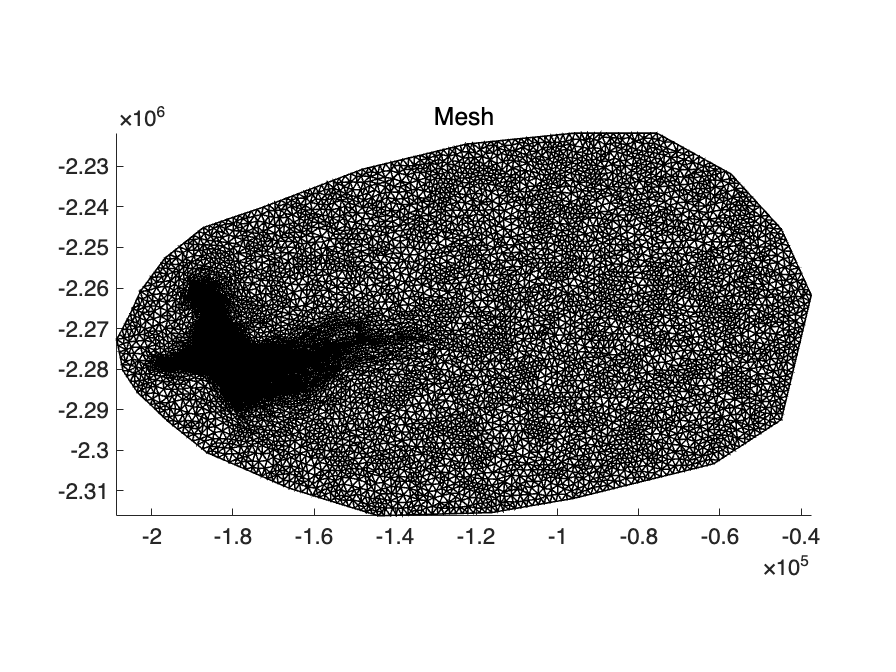

[md.mesh.lat,md.mesh.long] = xy2ll(md.mesh.x,md.mesh.y,+1,45,70);
md.mesh.epsg=3413;

% plot the mesh to check the triangle adjustment
plotmodel(md,'data','mesh')

## Parameterization of the model

% Step - 1 Interpolate the datasets from the Bedmachine-Greenland-v5
md=setflowequation(md,'SSA','all'); % Set flow law to SSA for original 2d mesh
md=setmask(md,'','');
md=parameterize(md,'/Users/rishi/Desktop/ISSM/examples/Jakobshavn/Greenland.par'); % can be used for any Greenland glacier

   Interpolating mask
   -- BedMachine Greenland version: v5
   -- BedMachine Greenland: loading mask
   -- BedMachine Greenland: interpolating mask
       -- Interpolation method: nearest
      reading MC bed (assumes no floating ice)
   -- BedMachine Greenland version: v5
   -- BedMachine Greenland: loading bed
   -- BedMachine Greenland: interpolating bed
       -- Interpolation method: cubic
      reading Howat surface
   -- BedMachine Greenland version: v5
   -- BedMachine Greenland: loading surface
   -- BedMachine Greenland: interpolating surface
       -- Interpolation method: cubic
   Adjusting ice mask
      -- reconstruct thickness
      reading velocities 
   Creating flow law parameters (assume ice is at 0°C for now)
   Geothermal flux from Shapiro et al.
   Setting up thermal model
   Set Boundary conditions


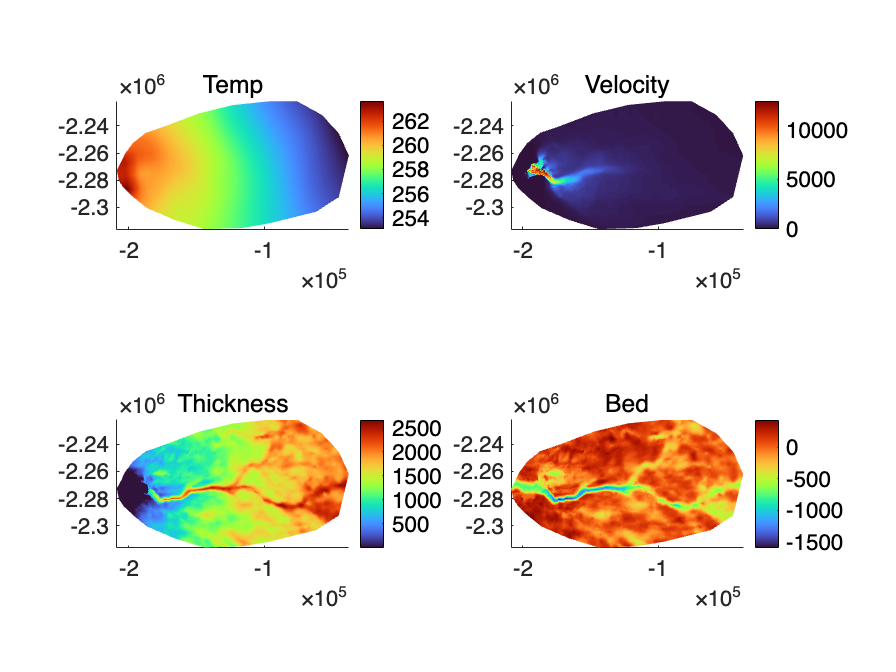

md.miscellaneous.name = 'Jacob';


% Plot the parameters interpolated from the input data
plotmodel(md,'data', ...
    md.initialization.temperature,'title','Temp', ...
    'data', md.initialization.vel,'title','Velocity', ...
    'data',md.geometry.thickness,'title','Thickness', ...
    'data',md.geometry.bed,'title','Bed')

## Model parameterters for running ISSM - Greenland

%Control general
md.inversion=m1qn3inversion(md.inversion);
md.inversion.iscontrol=1;
md.verbose=verbose('solution',false,'control',true);
md.transient.amr_frequency = 0;


%Cost functions
md.inversion.cost_functions=[101 501];
md.inversion.cost_functions_coefficients=zeros(md.mesh.numberofvertices,2);
md.inversion.cost_functions_coefficients(:,1)=50;
md.inversion.cost_functions_coefficients(:,2)= 2e-9;
pos=find(md.mask.ocean_levelset<0 | md.mask.ice_levelset>0);
md.inversion.cost_functions_coefficients(pos,1:2)=0;
md.stressbalance.spcvx(pos)=md.initialization.vx(pos);
md.stressbalance.spcvy(pos)=md.initialization.vy(pos);


%Controls
md.inversion.control_parameters={'FrictionCoefficient'}; % parameters to invert
md.inversion.maxsteps=100; % maximum steps of inversion
md.inversion.maxiter =100; % maximum iterations
md.inversion.min_parameters=0.05*ones(md.mesh.numberofvertices,1);
md.inversion.max_parameters=300*ones(md.mesh.numberofvertices,1);
md.inversion.control_scaling_factors=1;


%Additional parameters
md.stressbalance.restol= 0.01;
md.stressbalance.reltol= 0.1;
md.stressbalance.abstol= NaN;
md.initialization.pressure=zeros(md.mesh.numberofvertices,1);


%Go solve
md.cluster=generic('name',oshostname,'np',4);
md=solve(md,'sb');

uploading input file and queuing script
launching solution sequence on remote cluster

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
   Initialize M1QN3 parameters
   Computing initial solution

┌────┬─────────────────┬────────────┬────────────────────────┐
│Iter│  Cost function  │ Grad. norm │  List of contributions │
├────┼─────────────────┼────────────┼────────────────────────┤
│  1 │ f(x)=    146.37 │      0.585 │     146.4 5.341e-35    │
│  2 │ f(x)=    48.118 │     0.0936 │     48.12 6.481e-05    │
│  3 │ f(x)=    39.301 │     0.0683 │      39.3 8.449e-05    │
│  4 │ f(x)=    23.388 │     0.0564 │     23.39 0.0001908    │
│  5 │ f(x)=     16.65 │     0.0424 │     16.65 0.0004199    │
│  6 │ f(x)=    13.318 │      0.025 │     13.32 0.0004927    │
│  7 │ f(x)=    11.067 │     0.0248 │     11.07 0.0006574    │
│  8 │ f(x)=    10.308 │     0.0136 │     10.31 0.0007298    │

## Plot the oberved and modelled velocity with friction coefficient

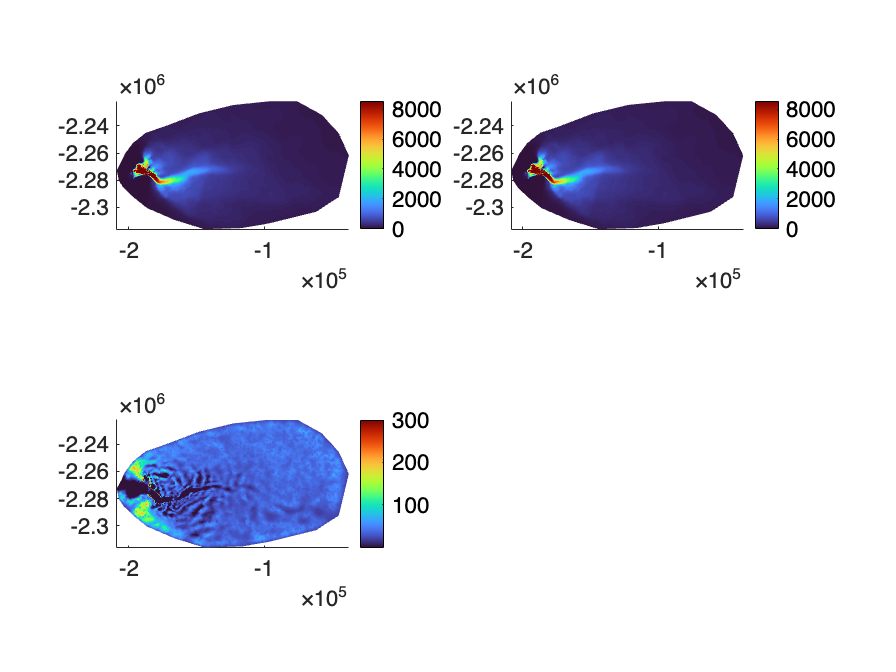

plotmodel(md,'data', md.initialization.vel,'caxis#1',[0 8500],...
'data',md.inversion.vel_obs,'caxis#2',[0 8500],...
'data',md.results.StressbalanceSolution.FrictionCoefficient)

## Calculate Mechanical properties of ice - Stress and Strain

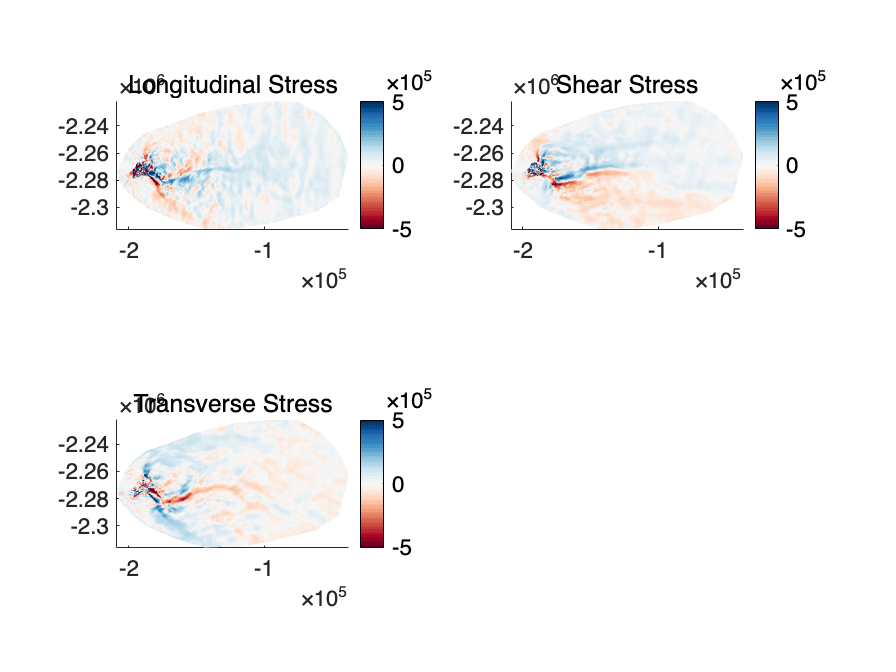

md = mechanicalproperties(md, md.results.StressbalanceSolution.Vx, ...
    md.results.StressbalanceSolution.Vy);

% plot the stresses
plotmodel(md,'data',md.results.deviatoricstress.xx,'caxis#1',[-5e5 5e5],'title','Longitudinal Stress', ...
    'data',md.results.deviatoricstress.xy,'caxis#2',[-5e5 5e5],'title','Shear Stress', ...
    'data',md.results.deviatoricstress.yy,'caxis#3',[-5e5 5e5],'title','Transverse Stress')

colormap(brewermap(50,'RdBu'))

## THERMAL STEADY STATE SOLUTION FOR GLACIER

% make the glacier layers for modelling
md=extrude(md,5,1.2);
md=setflowequation(md,'HO','all'); % Set flow law to HO for 3D mesh
md.thermal.fe = 'P1xP2';
md.inversion.iscontrol=0;


%Set single point constraints of surface temperature as boundary conditions
md.thermal.spctemperature(find(md.mesh.vertexonsurface))=...
    md.initialization.temperature(find(md.mesh.vertexonsurface));

%Initialize thermal paramertes
md.initialization.enthalpy = zeros(md.mesh.numberofvertices,1);
md.thermal.isdrainicecolumn=0;

%Run a steady state heat equation solution
md.timestepping.time_step=0;
md.cluster=generic('name',oshostname,'np',4);
md=solve(md,'thermal');

uploading input file and queuing script
launching solution sequence on remote cluster

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
write lock file:

   FemModel initialization elapsed time:   0.151572
   Total Core solution elapsed time:       8.6457 
   Linear solver elapsed time:             5.53111 (64%)

   Total elapsed time: 0 hrs 0 min 8 sec


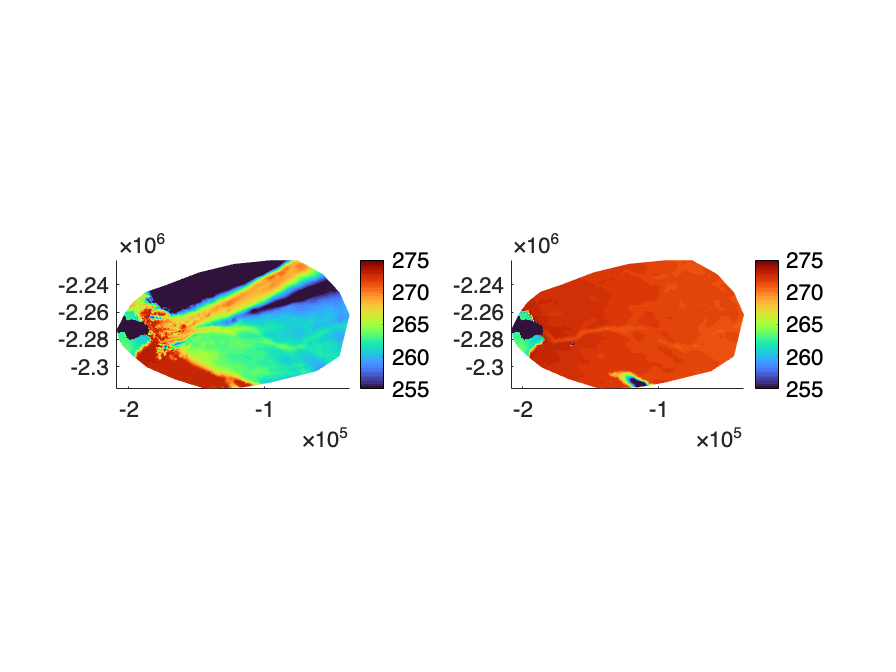


%Put results back into the model
md.initialization.temperature=md.results.ThermalSolution.Temperature;
md.initialization.enthalpy=md.results.ThermalSolution.Enthalpy;
md.materials.rheology_B = cuffey(md.initialization.temperature);

% Plot the surface temperature and temperature in basal layer
plotmodel(md,'data', md.initialization.temperature,'layer#1',4,'data', ...
md.initialization.temperature,'layer#2',1, 'caxis#all',[255 275])

%Set thermal lateral boundary conditions on all ice that is entering the domain.
%No single point constraints should be set on ice flowing out of the domain
% (i.e. ice sheet boundary or ocean locations)
md.thermal.spctemperature(md.mesh.vertexonboundary & md.mask.ice_levelset<0)...
=md.initialization.temperature(md.mesh.vertexonboundary & md.mask.ice_levelset<0);

%Turn off control for inversion
md.inversion.iscontrol=0;
md.timestepping.time_step=0;
md=solve(md,'ss');

uploading input file and queuing script
launching solution sequence on remote cluster

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
write lock file:

   FemModel initialization elapsed time:   0.264745
   Total Core solution elapsed time:       59.2983
   Linear solver elapsed time:             46.8285 (79%)

   Total elapsed time: 0 hrs 0 min 59 sec


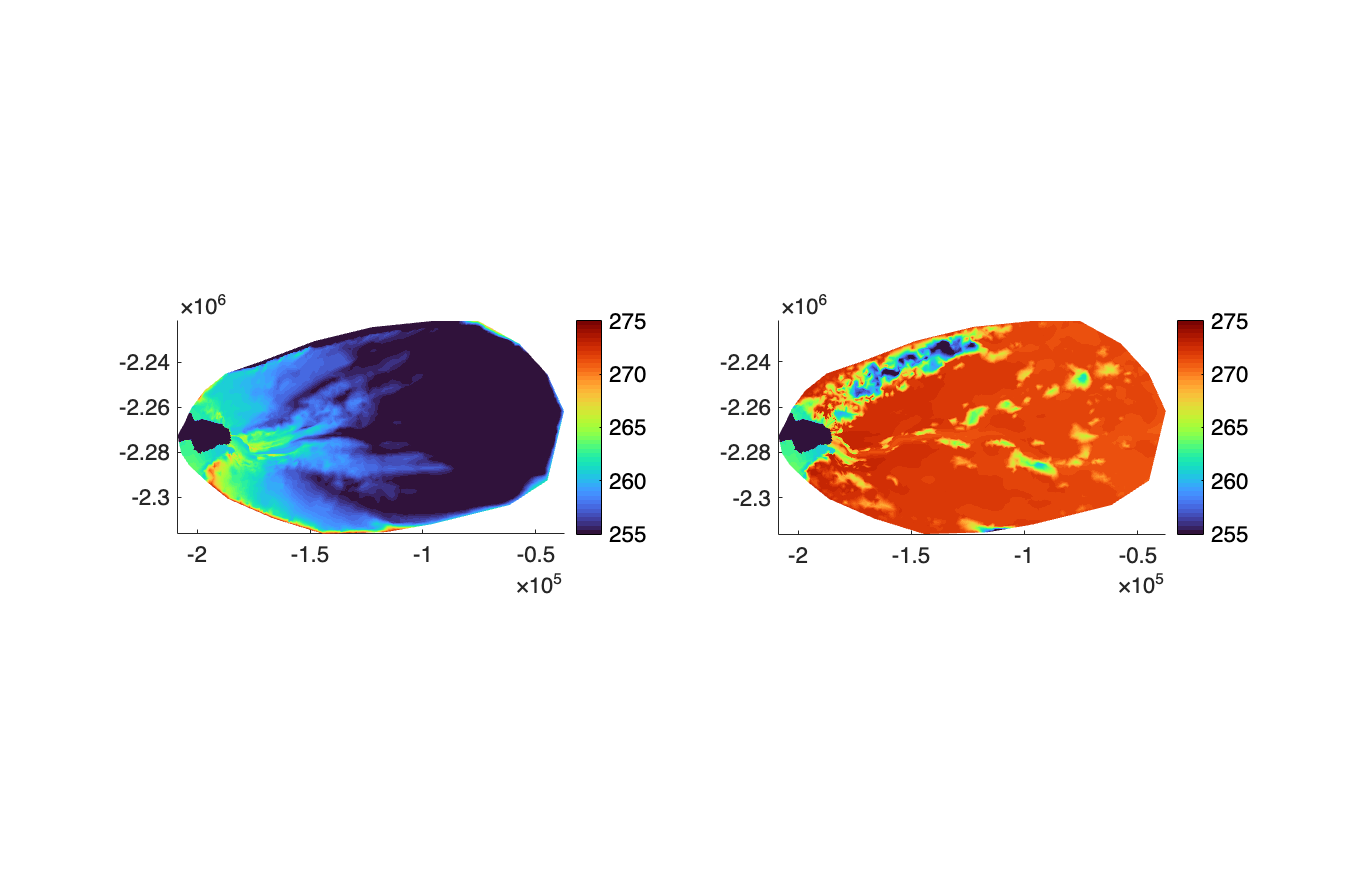


%Put results back into the model
%Save steady state results in intitalization temperature
md.initialization.temperature = md.results.SteadystateSolution.Temperature;

%Save steady state results in intitalization enthalpy
md.initialization.enthalpy = md.results.SteadystateSolution.Enthalpy;

%Call the cuffey function to calculate materials rheology_B and save it in the model
md.materials.rheology_B = cuffey(md.initialization.temperature);

plotmodel(md,'figposition','fullscreen','data', md.initialization.temperature,...
'layer#1',4,'data',md.initialization.temperature,'layer#2',1,'caxis#all',[255 275])

%Save the model in a temporary variable.
md3d=md;
%Collapse the new 3D model variable to 2D and save it in md.
md=collapse(md3d);
%Set the new flow equation to SSA for a 2D model
md=setflowequation(md,'SSA','all'); % Set flow law to SSA for original 2d mesh
%Depth average the 3D model temperature, run the cuffey algorithm to calcuate a new 2D rheology_B
md.materials.rheology_B=cuffey(DepthAverage(md3d,md3d.results.SteadystateSolution.Temperature));
%Restrict the maximum rheology_B to 4*10^8
md.materials.rheology_B(find(md.materials.rheology_B>4*10^8))=4*10^8;

%Cost functions
md.inversion.cost_functions=[101 103 501];
md.inversion.cost_functions_coefficients=zeros(md.mesh.numberofvertices,3);
md.inversion.cost_functions_coefficients(:,1)=50;
md.inversion.cost_functions_coefficients(:,2)=3;
md.inversion.cost_functions_coefficients(:,3)= 1e-7;
pos=find(md.mask.ocean_levelset<0 | md.mask.ice_levelset>0);
md.inversion.cost_functions_coefficients(pos,:)=0;
md.stressbalance.spcvx(pos)=md.initialization.vx(pos);
md.stressbalance.spcvy(pos)=md.initialization.vy(pos);

%Controls
md.inversion.control_parameters={'FrictionCoefficient'};
md.inversion.maxsteps=100;
md.inversion.maxiter =100;
md.inversion.min_parameters=0.05*ones(md.mesh.numberofvertices,1);
md.inversion.max_parameters=300*ones(md.mesh.numberofvertices,1);
md.inversion.control_scaling_factors=1;

%Control general
md.inversion.iscontrol=1;
md.verbose=verbose('solution',false,'control',true);

%Go solve
md.cluster=generic('name',oshostname,'np',4);
md=solve(md,'sb');

uploading input file and queuing script
launching solution sequence on remote cluster

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
   Initialize M1QN3 parameters
   Computing initial solution

┌────┬─────────────────┬────────────┬──────────────────────────────┐
│Iter│  Cost function  │ Grad. norm │  List of contributions       │
├────┼─────────────────┼────────────┼──────────────────────────────┤
│  1 │ f(x)=    424.78 │      0.881 │     143.3     281.4 2.671e-33│
│  2 │ f(x)=    122.13 │      0.149 │     28.52      93.6   0.01364│
│  3 │ f(x)=    94.315 │      0.102 │      23.6      70.7   0.01917│
│  4 │ f(x)=    52.251 │      0.046 │     15.73     36.47    0.0428│
│  5 │ f(x)=    37.172 │     0.0454 │     14.01     23.09   0.07496│
│  6 │ f(x)=    28.671 │     0.0728 │      12.3     16.24    0.1216│
│  7 │ f(x)=    23.635 │     0.0251 │     8.993     14.48    0.1594│
│ 


%Put results back into the model
md.friction.coefficient=md.results.StressbalanceSolution.FrictionCoefficient;
md.initialization.vx=md.results.StressbalanceSolution.Vx;
md.initialization.vy=md.results.StressbalanceSolution.Vy;
md.initialization.vel=md.results.StressbalanceSolution.Vel;
md.stressbalance.spcvx(pos)=nan;
md.stressbalance.spcvy(pos)=nan;

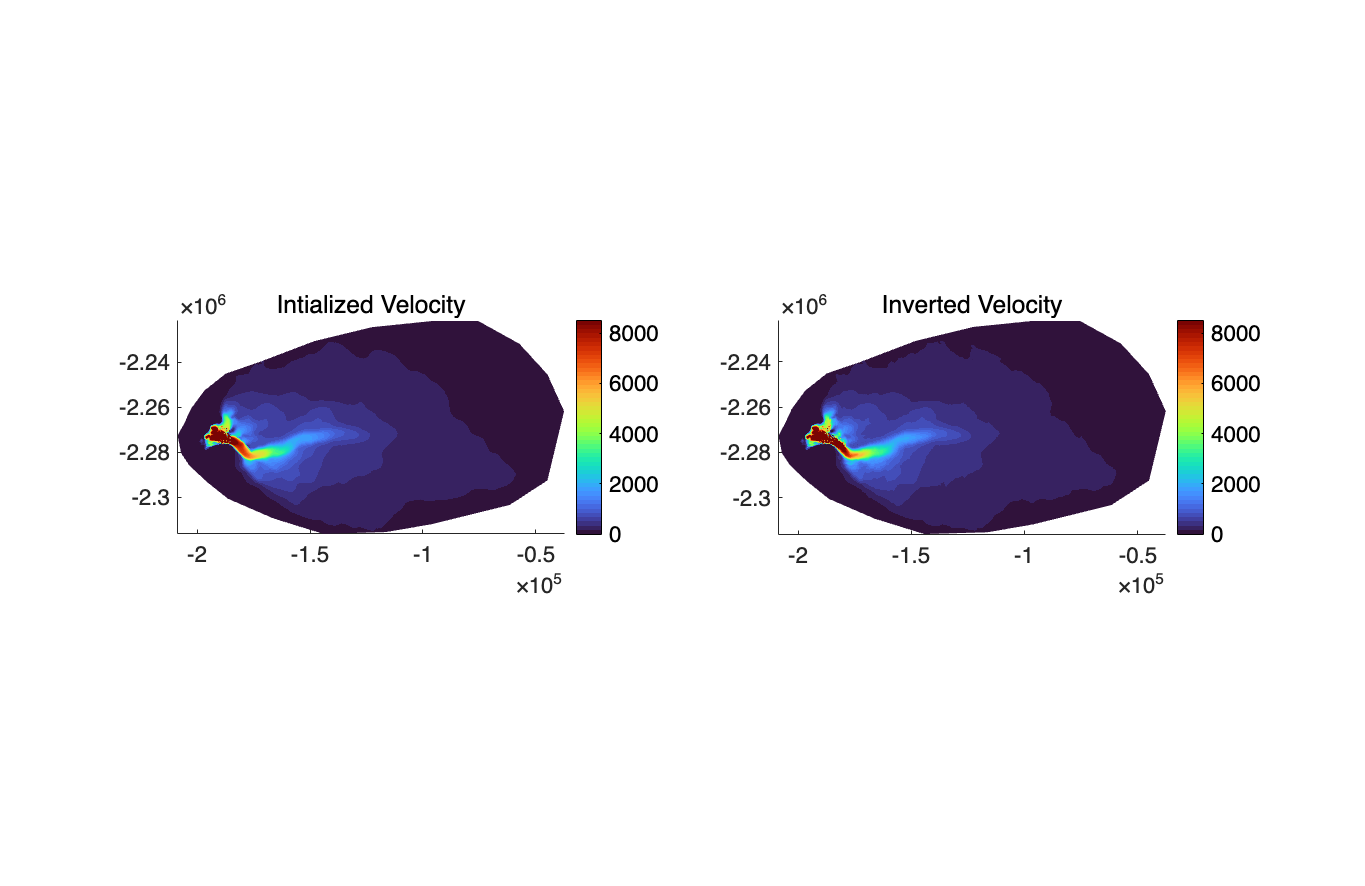

% Plot the surface velocity and basal friction
plotmodel(md,'data', md.initialization.vel,'title','Intialized Velocity', ...
'data',md.inversion.vel_obs,'title','Inverted Velocity','caxis#all',[0 8500])

## Plot other variables

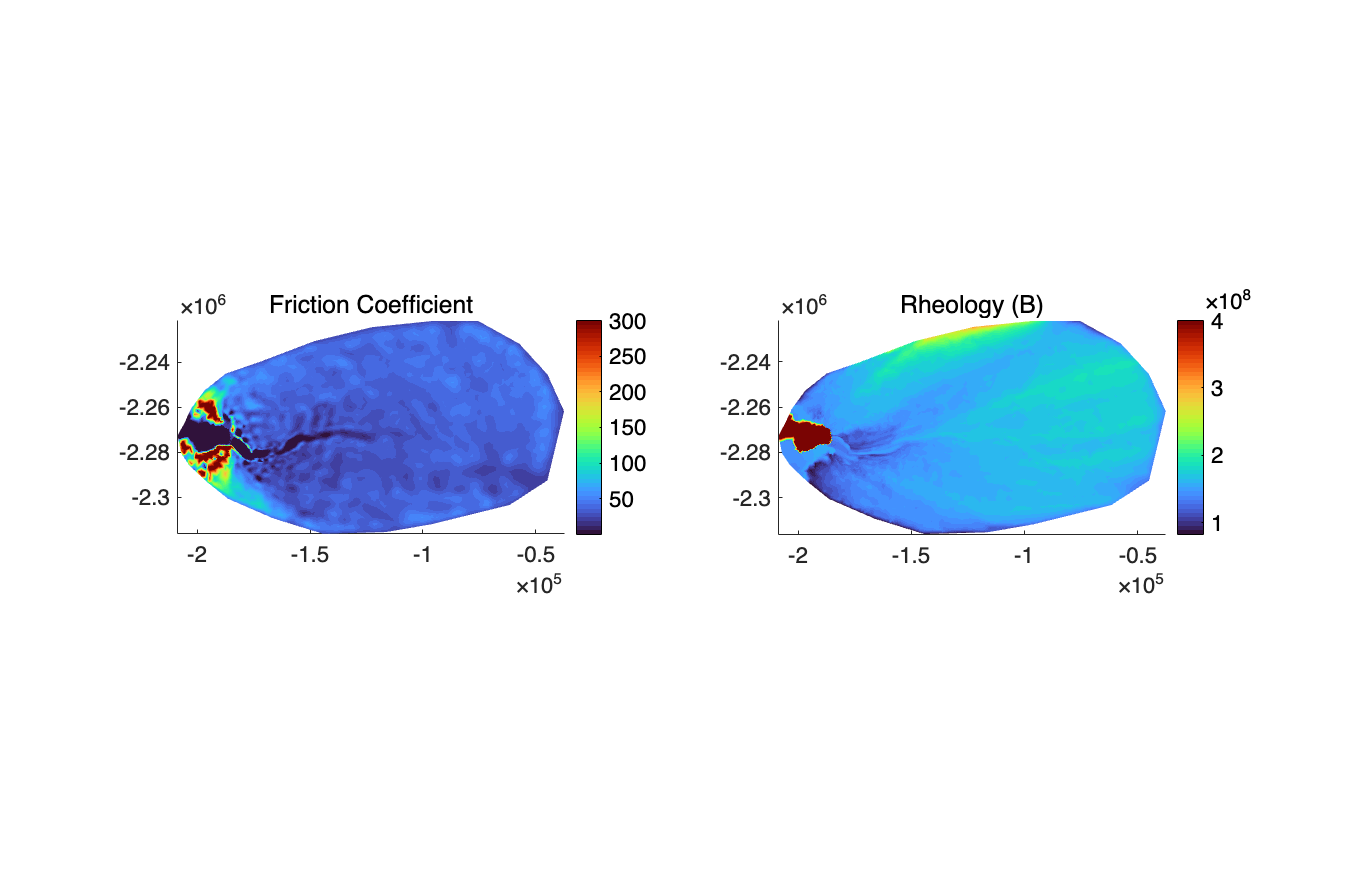

plotmodel(md,'data', md.results.StressbalanceSolution.FrictionCoefficient,'title','Friction Coefficient',...
'data',md.materials.rheology_B,'title','Rheology (B)')